clc;clear;
close all;


% manually inputted rat data
rat = 1:1:20; 
rat = rat' 

rat =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


RATio = [0.8889;0.75;0.833;0.2078;0.1616;0.1647;.290;0.397;0.3333;0.1519;0.1647;0.968;0.4358;0.238;0.5628;0.3314;0.3287;0.282;0.365;.529]; 
areRAT = [51;37;20;32;28;26;32;24;27;21;24;38;79;69;141;62;343;250;405;423]

areRAT =     51
    37
    20
    32
    28
    26
    32
    24
    27
    21


pain = [0;0;0;1;1;1;1;1;1;1;1;0;1;1;0;1;1;1;1;0];
logratio = -log(RATio);
data = table(rat,pain,RATio,logratio,areRAT); 
disp(data);

    rat    pain    RATio     logratio    areRAT
    ___    ____    ______    ________    ______

     1      0      0.8889     0.11777      51  
     2      0        0.75     0.28768      37  
     3      0       0.833     0.18272      20  
     4      1      0.2078      1.5712      32  
     5      1      0.1616      1.8226      28  
     6      1      0.1647      1.8036      26  
     7      1        0.29      1.2379      32  
     8      1       0.397     0.92382      24  
     9      1      0.3333      1.0987      27  
    10      1      0.1519      1.8845      21  
    11      1      0.1647      1.8036      24  
    12      0       0.968    0.032523      38  
    13      1      0.4358     0.83057      79  
    14      1       0.238      1.4355      69  
    15      0      0.5628     0.57483     141  
    16      1

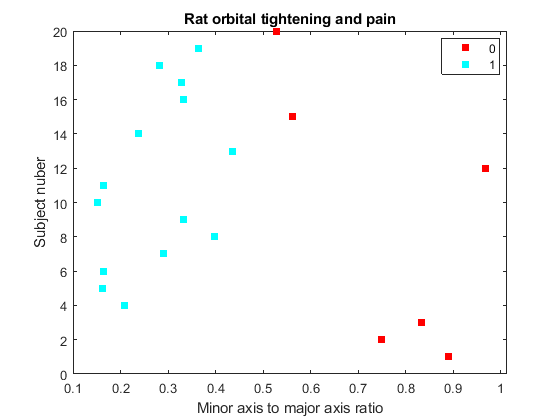


gscatter(data.RATio,data.rat,data.pain);
title('Rat orbital tightening and pain');
xlabel('Minor axis to major axis ratio');
ylabel('Subject nuber');

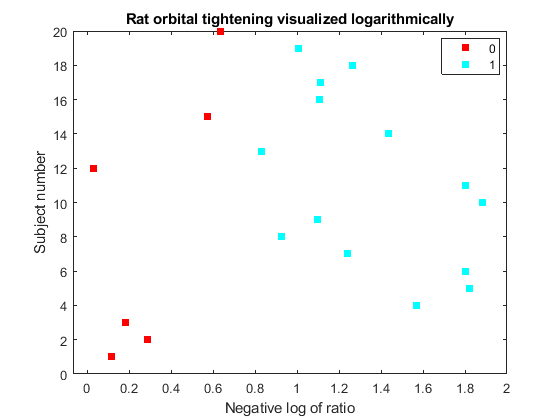


gscatter(data.logratio,data.rat,data.pain);
title('Rat orbital tightening visualized logarithmically');
xlabel('Negative log of ratio');
ylabel('Subject number');

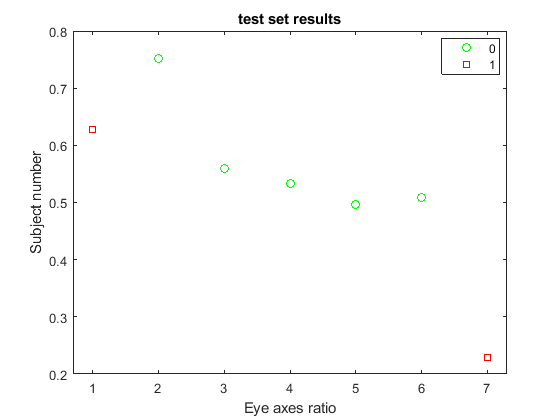

%first load a table of the specs for all/some test rats and label them with
%the ratio from the ratalyzer and actual pain. 
load testrats.mat;
trats = 1:1:7;
trats=trats';
T_paine = [1;0;0;0;0;0;1]; %these are the actual pain levels for error determination 
t_ratio = [0.6282;0.752;0.559;0.5328;0.4959;.509;0.2289]; %ratios for the test rats, trat1 was head on which made it seem rounder than it actually was
ttable = table(trats,T_paine,t_ratio);
gscatter(ttable.trats,ttable.t_ratio,ttable.T_paine,'gr','os');
title('test set results');
xlabel('Eye axes ratio');
ylabel('Subject number');

lda = fitcdiscr(data(:,[1,3]),data.pain);
ldaclass = resubPredict(lda);%i'm just doing homework seven again lmao 
ldaError = resubLoss(lda);
fprintf("Suh' dude. %.3f is the LDA error",ldaError);

Suh' dude. 0.050 is the LDA error

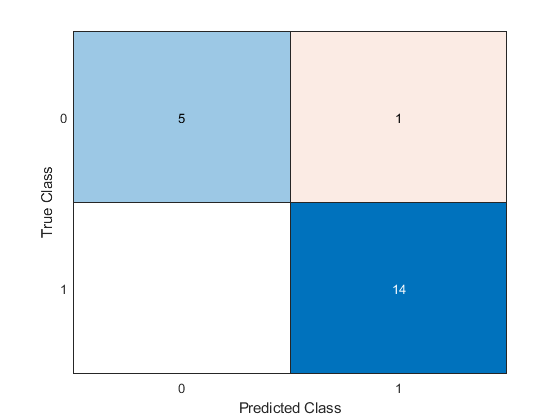


confumat = confusionchart(data.pain,ldaclass);

gscatter(data.rat,data.RATio,ldaclass,'gr','os');
title('Predicted pain');
xlabel('Rat number');
ylabel('Axis Eye Ratio');
% baddies = ~strcmp(data.pain,ldaclass);
baddies=ldaclass~=data.pain

baddies = 20×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0



% data = table(rat,pain,RATio,logratio,baddies)
matrix_data=table2array(data)  %convert table to matrix

matrix_data =     1.0000         0    0.8889    0.1178   51.0000
    2.0000         0    0.7500    0.2877   37.0000
    3.0000         0    0.8330    0.1827   20.0000
    4.0000    1.0000    0.2078    1.5712   32.0000
    5.0000    1.0000    0.1616    1.8226   28.0000
    6.0000    1.0000    0.1647    1.8036   26.0000
    7.0000    1.0000    0.2900    1.2379   32.0000
    8.0000    1.0000    0.3970    0.9238   24.0000
    9.0000    1.0000    0.3333    1.0987   27.0000
   10.0000    1.0000    0.1519    1.8845   21.0000


rat_num=matrix_data(baddies,1)

rat_num = 20

rat_ratio=matrix_data(baddies,3)

rat_ratio = 0.5290

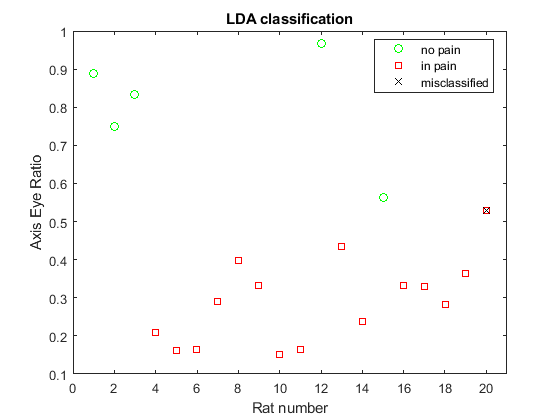

hold on;
plot(rat_num,rat_ratio,'kx');
title('LDA classification');
legend('no pain','in pain','misclassified');
hold off; 

[x,y] = meshgrid(0:1:20,0:.05:1.5);
x = x(:);
y = y(:);
j = predict(lda,[x,y]);
gscatter(x,y,j,'grb','osk');
title('LDA decision boundary');
ylabel('eye axes ratio');
xlabel('Subject number');



Create diagram tree

dt=fitctree(data(:,[1,3]),data.pain,'PredictorNames',{'RATio','rat'})

dt =   ClassificationTree
           PredictorNames: {'RATio'  'rat'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 20


  Properties, Methods


dt_Class=resubPredict(dt)

dt_Class =      0
     0
     0
     1
     1
     1
     1
     1
     1
     1


dt_ResubErr=resubLoss(dt) 

dt_ResubErr = 0


[dt_ResubCM, grpOrder]=confusionmat(pain, dt_Class)

dt_ResubCM =      6     0
     0    14


grpOrder =      0
     1


dt_bad=dt_Class~=data.pain

dt_bad = 20×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


dt_rat_num=matrix_data(dt_bad,1)


dt_rat_num =

  0×1 empty double column vector



dt_rat_ratio=matrix_data(dt_bad,3)


dt_rat_ratio =

  0×1 empty double column vector



hold on
plot(dt_rat_num,dt_rat_ratio,'kx')

**Step 22) (1 point) **Add title "Decision Tree Classification" and using fucntion legend add three items in legend: "survived", "deceased", "misclassified" and use `hold off `command after adding legends (3 lines) 

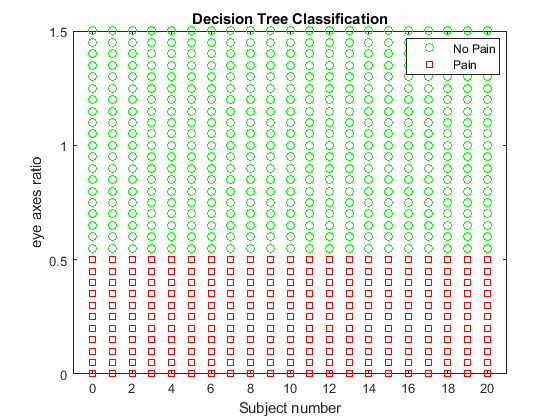

title('Decision Tree Classification')
legend('No Pain','Pain','misclassified')
hold off

**Step 23) (1 point) **Visualize the region separation using meshgrid and gscatter functions (up to 5 lines)

[x,y]=meshgrid(0:1:20,0:.05:1)

x =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    1

y =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500
    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000
    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500    0.1500
    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000  

x=x(:);
y=y(:);
j=predict(lda, [x,y])

j =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


gscatter(x,y,j,'grb','sod')

**Step 24) (1 point) **Add title "Decision Tree Boundary", x-label "Year of Operation", and y-label "Number of positive axillary nodes") (3 lines)

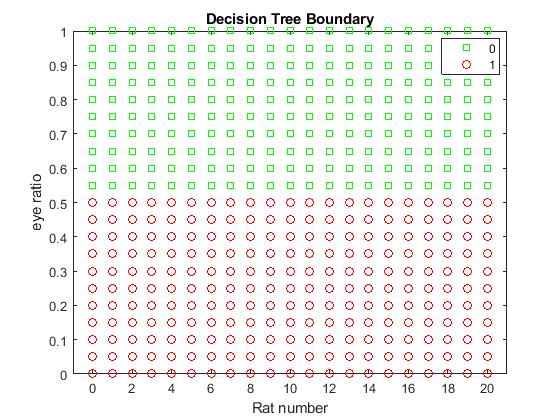

title('Decision Tree Boundary')
xlabel('Rat number')
ylabel('eye ratio')

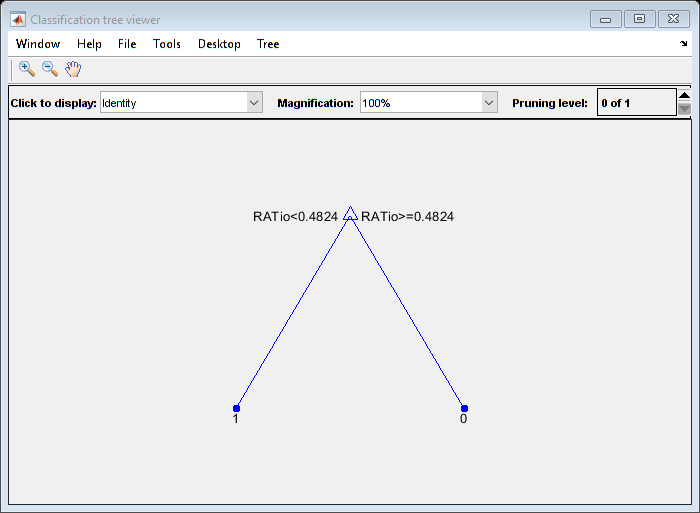

view(dt,'Mode','graph')